% (1) simulate threshold and intensity data
% (2) fit models back


## generate threshold data

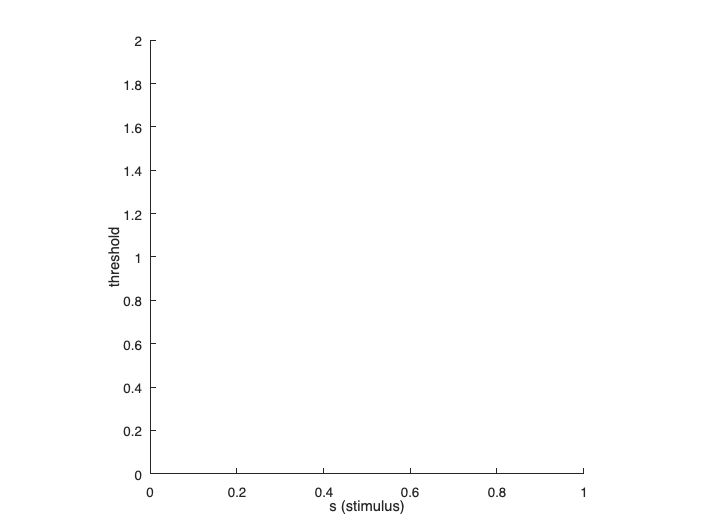

% threshold function

mk_threshold = @(s, w, d, beta) ((s + d).^beta)./w;

w = 0.6;
s = linspace(5, 80, 10);
d = 0.6;
beta = 1.5;

threshold = mk_threshold(s, w, d, beta);

figure (1), clf
plot(s, threshold, 'ko:')
xlabel('s (stimulus)'), ylabel('threshold'), box off, ylim([0, 2]), axis square

## generate intensity data

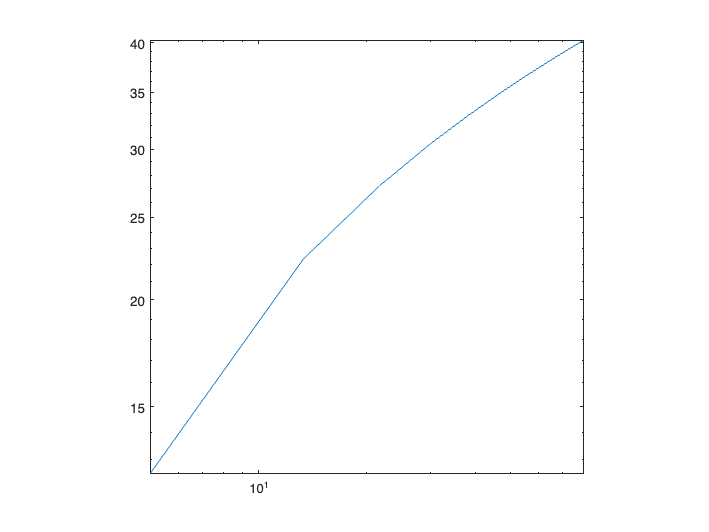

% Here, I use a 

mk_intensity = @(s, p1, p2) log(.7 * s);

p1 = .8; 
p2 = .8;

intensity = 10 .* mk_intensity(s, p1, p2);

figure (2), clf
loglog(s, intensity), axis square

## initiate model fitting (add noise to data)

f = [];

f.thresh_dt = threshold + normrnd(0, 0.01, size(s));
f.intensity_dt = intensity + normrnd(0, 0.01, size(s));

## fit threshold data

% fitting function
loss_thresh = @(s, w, d, beta, dt) sum((log(mk_threshold(s, w, d, beta))- log(dt)).^2);

thresh_init = [1, 0.5, 1.5];

% fitting threshold data
f.thresh_prm = fminsearch(@(x) loss_thresh(s, x(1), x(2), x(3), f.thresh_dt), thresh_init);

% plot threshold fit
f.thresh_axis = linspace(min(s), max(s), 100);
f.thresh_prd  = mk_threshold(f.thresh_axis, f.thresh_prm(1), f.thresh_prm(2), f.thresh_prm(3));


## plot threshold data fit

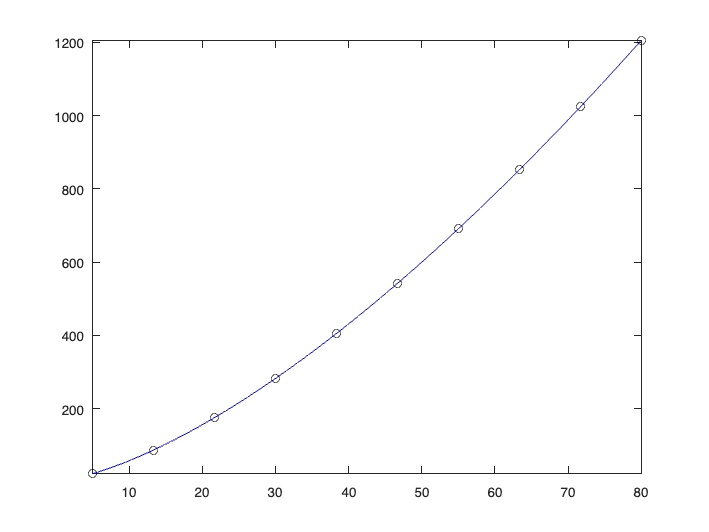

figure (1), clf
plot(s, f.thresh_dt, 'ko'), hold on
plot(f.thresh_axis, f.thresh_prd, 'b-')

## make predictions to intensity data

## modulated Poisson model (full noise model)

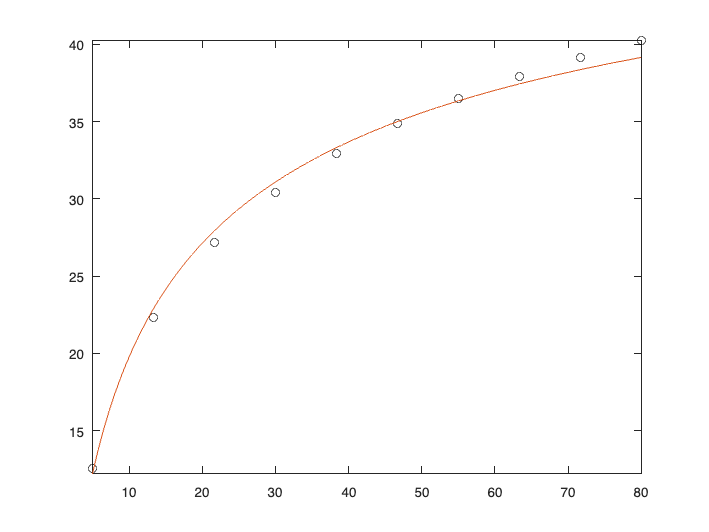

loss1 = @(s, d, w, beta, c, g, sc, dt) sum((log(mkPercept(s, d, w, beta, c, g, sc)) - log(dt)).^2);

% mp_init 
% fit
init = [5, 3, 2]; % 5, 3, 2 for log

f.perc_prm_fullmodel = fminsearch(@(x) loss1(s, f.thresh_prm(1), f.thresh_prm(2), f.thresh_prm(3), x(1), x(2), x(3), f.intensity_dt), init);

% make model prediction
f.perc_prd_fullmodel = mkPercept(f.thresh_axis, f.thresh_prm(1), f.thresh_prm(2), f.thresh_prm(3), f.perc_prm_fullmodel(1), f.perc_prm_fullmodel(2), f.perc_prm_fullmodel(3));

% visualize the model fit
figure (2), clf
plot(s, f.intensity_dt, 'ko'), hold on
plot(f.thresh_axis, f.perc_prd_fullmodel)

## Additive model

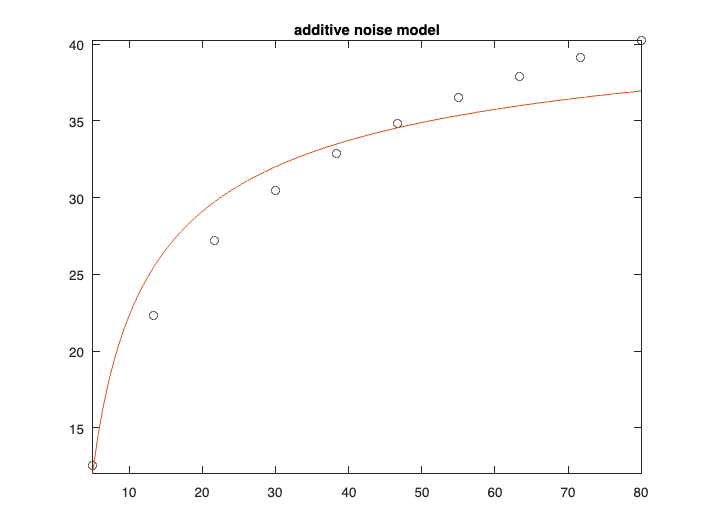

loss2 = @(s, d, w, beta, sigma, c, sc, dt) sum((log(mkPercept_additive(s, d, w, beta, sigma, c, sc)) - log(dt)).^2);


init = [2, 50000, 20];

%low  = [1e-5, -100, 0];
%high = [1000, 1000, 100000];
%f.perc_prm_additive = fmincon(@(x) loss2(s, f.thresh_prm(1), f.thresh_prm(2), f.thresh_prm(3), x(1), x(2), x(3), f.intensity_dt), init, [],[],[],[], low, high);
f.perc_prm_additive = fminsearch(@(x) loss2(s, f.thresh_prm(1), f.thresh_prm(2), f.thresh_prm(3), x(1), x(2), x(3), f.intensity_dt), init);

% make model predictions
f.perc_prd_additive = mkPercept_additive(f.thresh_axis, f.thresh_prm(1), f.thresh_prm(2), f.thresh_prm(3), f.perc_prm_additive(1), f.perc_prm_additive(2), f.perc_prm_additive(3));

figure (2), clf
plot(s, f.intensity_dt, 'ko'), hold on
plot(f.thresh_axis, f.perc_prd_additive), title('additive noise model')

## Multiplicative model

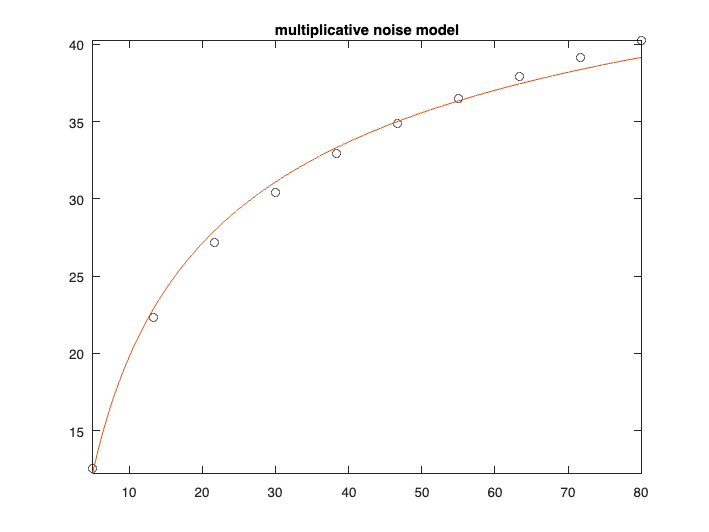

loss3 = @(s, d, w, beta, c, g, sc, dt) sum((log(mkPercept_multiplicative(s, d, w, beta, c, g, sc)) - log(dt)).^2);


init = [1, 0.1, .8];

f.perc_prm_multiplicative = fminsearch(@(x) loss3(s, f.thresh_prm(1), f.thresh_prm(2), f.thresh_prm(3), x(1), x(2), x(3), f.intensity_dt), init);

% make model predictions
f.perc_prd_multiplicative = mkPercept_multiplicative(f.thresh_axis, f.thresh_prm(1), f.thresh_prm(2), f.thresh_prm(3), f.perc_prm_multiplicative(1), f.perc_prm_multiplicative(2), f.perc_prm_multiplicative(3));

figure (2), clf
plot(s, f.intensity_dt, 'ko'), hold on
plot(f.thresh_axis, f.perc_prd_multiplicative), title('multiplicative noise model')

## Poisson model

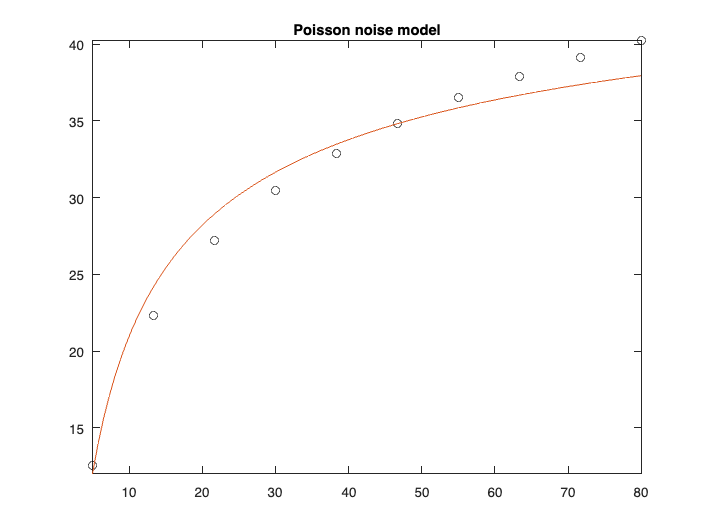

loss4 = @(s, d, w, beta, c, sc, dt) sum((log(mkPercept_poisson(s, d, w, beta, c, sc)) - log(dt)).^2);


init = [10, 29];

%low  = [-100, 0];
%high = [1000, 100000];
f.perc_prm_poisson = fminsearch(@(x) loss4(s, f.thresh_prm(1), f.thresh_prm(2), f.thresh_prm(3), x(1), x(2), f.intensity_dt), init);
% make model predictions
f.perc_prd_poisson = mkPercept_poisson(f.thresh_axis, f.thresh_prm(1), f.thresh_prm(2), f.thresh_prm(3), f.perc_prm_poisson(1), f.perc_prm_poisson(2));

figure (2), clf
plot(s, f.intensity_dt, 'ko'), hold on
plot(f.thresh_axis, f.perc_prd_poisson), title('Poisson noise model')

function output = mkPercept(s, d, w, beta, c, g, sc)

% s: stimulus, a vector
% d: the first constant from perceptual threshold fit
% w: the second constant from perceptual threshold fit
% beta: the third constant from perceptual threshold fit
% c: integration constant, to be fitted
% g: noise constant, to be fitted
% sc: scaling factor, to be fitted

step1 = w .* (d - s) + c .* (s - d).^beta;
step2 = g .* (s - d).^(-beta);
step3 = step1 .* step2 ./(2 * (beta - 1));
output = sinh(sc .* step3).^2./ g.^2;
end

% additive noise model ---------------------------------------
function output = mkPercept_additive(s, d, w, beta, sigma, c, sc)

% s: stimulus, a vector
% d, w, beta: constants from perceptual threshold fit
% sigma; standard deviation of the internal representation, to be fitted
% c: integration constant, to be fitted
% g: noise constant, to be fitted
% sc: scaling factor, to be fitted
step1 = w .* sigma .* (s - d).^(1-beta);
step2 = step1 ./(1-beta) + c;
output = sc .* step2;
end

% multiplicative noise model ---------------------------------

function output = mkPercept_multiplicative(s, d, w, beta, c, g, sc)

% all parameters are as stated in the previous two functions
step1 = g .* w .* (s - d).^(1-beta);
step2 = exp(step1 ./(1 - beta)) .* c;
output = sc .* step2;
end

% Poisson noise model ----------------------------------------

function output = mkPercept_poisson(s, d, w, beta, c, sc)

% all parameters are as previously stated
step1 = (w .* (d - s) + (beta - 1).* c .* (s - d).^beta) .^2;
step2 = (s - d).^(-2 .* beta) .* step1;
output = sc .* step2 ./ (4 .* (beta - 1).^2);
end